clear all

%Constantes físicas
M = 1.0;      % cart mass [kg]
m = 0.1;      % pole mass [kg]
l = 0.5;      % pole half-length / COM distance [m]
g = 9.81;     % gravity [m/s^2]
%Initial conditions
x0 = [0,0,deg2rad(3),0]';

%Linear Model
A = [0 1 0 0;
     0 0 -(m*g)/M 0;
     0 0 0 1;
     0 0 ((M+m)*g)/(l*M) 0];
B = [0; 1/M; 0; -1/(l*M)];
C = [1 0 0 0];
D = zeros(1,1);
syslin = ss(A,B,C,D);

%LQG Design
%Weights LQR 
Q = diag([1,1,10,1]);
R = 0.1;
Klqr = lqr(syslin,Q,R);

% Kalman / LQE
G = B;
W = 1e-4;
V = 1e-4;
L = lqe(A, G, C, W, V);

% Controlador dinámico:
% xhat_dot = (A - B*K - L*C)*xhat + L*y
% u        = -K*xhat

Ak = A - B*Klqr - L*C;
Bk = L;
Ck = -Klqr;
Dk = zeros(size(B,2), size(C,1));

K_lqg = ss(Ak, Bk, Ck, Dk);

disp('K LQR = ');

K LQR = 


disp(Klqr);

   -3.1623   -5.7201  -46.0317  -10.4066




disp('L Kalman = ');

L Kalman = 


disp(L);

   1.0e+03 *

    0.0106
    0.0566
   -0.2725
   -1.2657




Acl = [A + B*Dk*C, B*Ck;
        Bk*C, Ak];
eig(Acl);

save_dir = "C:\Users\Personal\OneDrive\Documents\ONERA - Flow Stabilization\PYTHON\RL\Test\Cartpole_Controller\controller.mat";
save(save_dir, 'Ak', 'Bk', 'Ck', 'Dk','-v7')

%Discrete Controller
dt = 1e-3;
Ts = 1e-4; 
k_lqg_disc = c2d(K_lqg,Ts,'zoh');
eig(k_lqg_disc);
[Ad, Bd, Cd, Dd] = ssdata(k_lqg_disc);

%%%LOAD PYTHON DATA%%%
cartpole_cont_csv = readtable("continuous_controller_signals.csv",VariableNamingRule='preserve');
cartpole_disc_csv = readtable("discrete_controller_signals.csv",VariableNamingRule='preserve');

%%%PLOTS TO COMPARE CLOSED-LOOP DYNAMICS FROM PYTHON AND MATLAB%%%
Tsim_cont = out.cartpole_cont1.Time;
theta_cont = out.cartpole_cont1.Data(:,1);
F_raw_cont = out.cartpole_cont1.Data(:,2); 
F_sat_cont = out.cartpole_cont1.Data(:,3); 
%%%
Tsim_disc = out.cartpole_disc1.Time;
theta_disc = out.cartpole_disc1.Data(:,1); 
F_raw_disc = out.cartpole_disc1.Data(:,2);
F_sat_disc = out.cartpole_disc1.Data(:,3);
%%% 
Tsim_cont_csv = cartpole_cont_csv.t;
theta_cont_csv = cartpole_cont_csv.x;
F_raw_cont_csv = cartpole_cont_csv.u_raw_0;
F_sat_cont_csv = cartpole_cont_csv.u_sat_0;
%%%
Tsim_disc_csv = cartpole_disc_csv.t;
theta_disc_csv = cartpole_disc_csv.x;
F_raw_disc_csv = cartpole_disc_csv.u_raw_0;
F_sat_disc_csv = cartpole_disc_csv.u_sat_0;

%%% SAVE IMAGES FOR DIFFERENT TESTING
save_dir_fig = "C:\Users\Personal\OneDrive\Documents\ONERA - Flow Stabilization\PYTHON\RL\Test\Cartpole_Controller\build_cartpole_minimal\Controller_Test";
folder_name = save_dir_fig;
if ~exist(folder_name, 'dir')
    mkdir(folder_name);
end

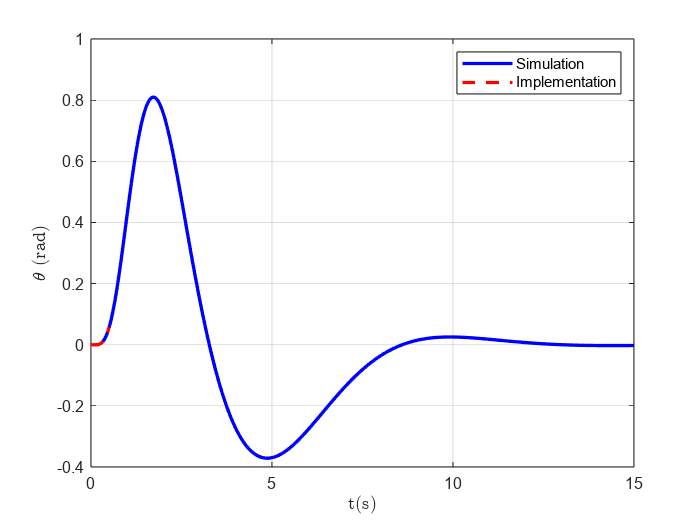

clf
%%%COMPARISON PLOTS : CONTINUOUS DYNAMICS
plot(Tsim_cont,theta_cont,Color="b",LineWidth=2)
xlabel('t(s)', Interpreter='latex')
ylabel('$\theta$ (rad)', Interpreter="latex")
hold on 
plot(Tsim_cont_csv,theta_cont_csv,Color="r",LineWidth=2,LineStyle="--")
grid on
legend({'Simulation: Matlab','Implementation: Python'})
xlim([0 Tsim_cont(end)])
hold off
sgtitle(sprintf('Continuous) Cartpole + Controller:  $\\theta_0 = %.2g$, $dt = %.1e$, $T_s = %.e$',x0(3), dt, Ts), ...
    'Interpreter', 'latex')
%%%SAVE IMAGE 
filename = fullfile(folder_name, 'closed_loop_continuous_LQG.png');
exportgraphics(gcf, filename, 'Resolution', 300)

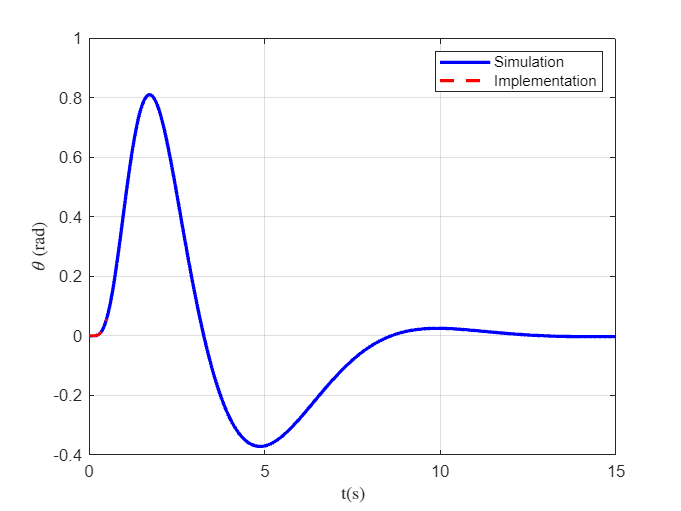

clf
%%%COMPARISON PLOTS : DISCRETE DYNAMICS
plot(Tsim_disc,theta_disc,Color="b",LineWidth=2)
xlabel('t(s)', Interpreter='latex')
ylabel('$\theta$ (rad)', Interpreter="latex")
hold on 
plot(Tsim_disc_csv,theta_disc_csv,Color="r",LineWidth=2,LineStyle="--")
grid on
legend({'Simulation','Implementation'})
xlim([0 Tsim_disc(end)])
hold off
%%%SAVE IMAGE 
filename = fullfile(folder_name, 'closed_loop_Hybrid_LQG.png');
exportgraphics(gcf, filename, 'Resolution', 300)

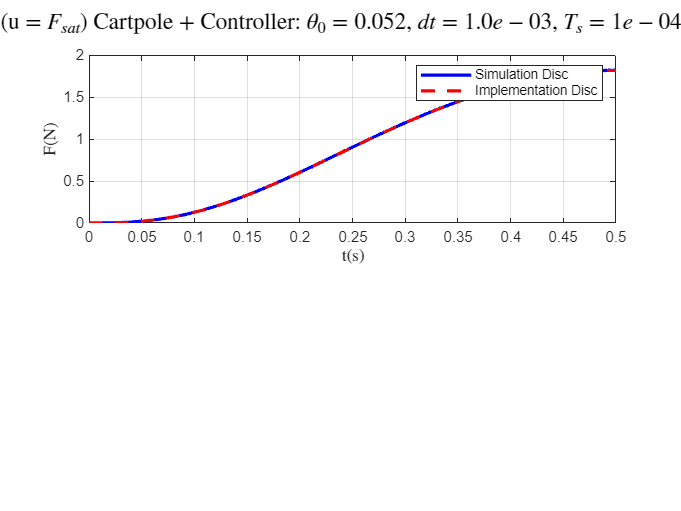

clf
%%%COMPARISON PLOTS
subplot(2,1,1)
plot(Tsim_cont,F_sat_cont,Color="b",LineWidth=2)
xlabel('t(s)', Interpreter='latex')
ylabel("F(N)", Interpreter="latex")
hold on 
plot(Tsim_cont_csv,F_sat_cont_csv,Color="r",LineWidth=2,LineStyle="--")
grid on
legend({'Simulation Cont','Implementation Cont'})
xlim([0 0.5])
hold off
%%%
% subplot(2,1,2)
% stairs(Tsim_disc,F_sat_disc,Color="b",LineWidth=2)
% xlabel('t(s)', Interpreter='latex')
% ylabel("F(N)", Interpreter="latex")
% hold on 
% stairs(Tsim_disc_csv,F_sat_disc_csv,Color="r",LineWidth=2,LineStyle="--")
grid on
legend({'Simulation Disc','Implementation Disc'})
xlim([0 0.5])
hold off
sgtitle(sprintf('(u = $F_{sat}$) Cartpole + Controller:  $\\theta_0 = %.2g$, $dt = %.1e$, $T_s = %.e$',x0(3), dt, Ts), ...
    'Interpreter', 'latex')
%%%SAVE IMAGE 
filename = fullfile(folder_name, 'closed_loop_SatForce_LQG.png');
exportgraphics(gcf, filename, 'Resolution', 300)